# A Nonlinear, 6-DOF Dynamic Model of Aircraft: -

# The Research Civil Aircarft Model.                                                       

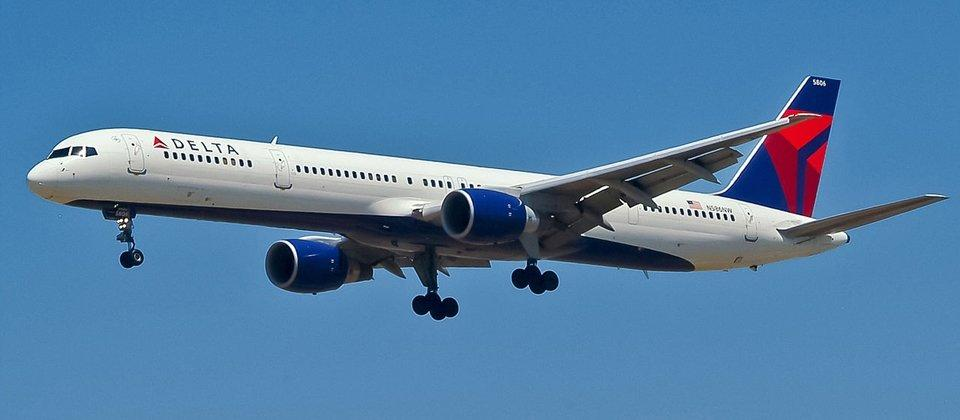

## Link for the Garteur web page [GARTEUR](https://www.youtube.com/redirect?event=video_description&redir_token=QUFFLUhqa0VnaC1PQWFjalN5bHBsZjlyTmJPenZxcV9Jd3xBQ3Jtc0tsV3NPV053bktfY2c2ZURxTURUMENYV1QyTU9pUVltQlQ0dUc2aUpiLVJsZ3Fha2VWcVBELWFCX0pfb09CczZnSWdnWDIzR2hxcmY1NjBqb20wa3FjNlBqaHBVWTZsMlpSQklZcjczT0VHLWt4U2RhYw&q=https%3A%2F%2Fgarteur.org%2F&v=bFFAL9lI2IQ)

## Link for RCAM Document [RCAM Document](https://www.youtube.com/redirect?event=video_description&redir_token=QUFFLUhqbHB4NG9hcFpFbTEyc1ZxMVp5dTRJRmNiNjF5d3xBQ3Jtc0tsaWszQ2lNTDhnRFNYSVpDS0kyX0d3TmFpWk1OUlNlSmN2WlhKc05YX2NvR1BMVG1NU3hBTDRHcG44UzBFTW05c1ZmcDFtMzFoVjBlcmpvdmh4QklZSWpPNEZwcmdDMWhqSTZHTTRIczNra1NzaEdrcw&q=https%3A%2F%2Fgarteur.org%2Fwp-content%2Freports%2FFM%2FFM_AG-08_TP-088-3.pdf&v=bFFAL9lI2IQ)

Note:- Here we are trying to simulate the similar sircraft like Boing 757-200

function[XDOT]=RCAM_model(X,U)

## STATE VECTOR


$$\bar{X} =\left\lbrack \begin{array}{c}
u\;\left(\textrm{Velocity}\;\textrm{along}\;X\right)\\
v\;\left(\textrm{Velocity}\;\textrm{along}\;Y\right)\\
z\;\left(\textrm{Velocity}\;\textrm{along}\;Z\right)\\
p\;\left(\textrm{angular}\;\textrm{rate}\;\textrm{along}\;X\right)\\
q\;\left(\textrm{angular}\;\textrm{rate}\;\textrm{along}\;Y\right)\\
r\;\left(\textrm{angular}\;\textrm{rate}\;\textrm{along}\;Z\right)\\
\textrm{phi}\\
\textrm{theta}\\
\textrm{psi}
\end{array}\right\rbrack$$


% extract the state vector

x1=X(1);      % Velocity in body x axis
x2=X(2);      % Velocity in body y axis
x3=X(3);      % Velocity in body z axis
x4=X(4);      % angular rate in body x axis
x5=X(5);      % angular rate in body x axis
x6=X(6);      % angular rate in body x axis
x7=X(7);      % phi (Bank angle)
x8=X(8);      % theta (Pitch angle)
x9=X(9);      % phi (Yaw angle)


## CONTROL VECTOR


$$\bar{U} =\left\lbrack \begin{array}{c}
\textrm{u1}\;\left(\textrm{Aileron}\right)\\
\textrm{u2}\;\left(\textrm{Elevator}\right)\\
\textrm{u3}\;\left(\textrm{Rudder}\right)\\
\textrm{u4}\;\left(\textrm{Throttle}\;1\right)\\
\textrm{u5}\;\left(\textrm{Throttle}\;2\right)
\end{array}\right\rbrack$$


% extract the control vector

u1=U(1);      %d_A (aileron)
u2=U(2);      %d_T (stabilizer) here the whole horizontal stabilzer moves not the elevator
u3=U(3);      %d_R (rudder)
u4=U(4);      %d_th1 (throttle 1)
u5=U(5);      %d_th2 (throttle 2)



## CONSTANTS

Here we are trying to enter all the constant value by the RCAM research value.

- Note all values entered are in the SI unit.

% Nominal vehicle constants
m=120000;                   % Aircraft total mass

% NOTE:- We will define the Ib and invIb later

cbar=6.6;                  % Mean aerodynamic chord
lt=24.8;                   % Distance by AC of tail and body (m)
S=260;                     % Wing planform area (m^2)
St=64;                     % Tail planform area (m^2)

Xcg=0.23*cbar;             % X Position of cg in Fm (m)
Ycg=0;                     % Y Position of cg in Fm (m)
Zcg=0.10*cbar;             % Z Position of cg in Fm (m)

Xac=0.19*cbar;             % X position of aerodynamic center in Fm (m)
Yac=0;                     % Y position of aerodynamic center in Fm (m)
Zac=0;                     % Z position of aerodynamic center in Fm (m)

% Engine Constants
Xapt1=0;                   % X position of engine 1 force in Fm (m)
Yapt1=-7.94;               % Y position of engine 1 force in Fm (m)
Zapt1=-1.9;                % Z position of engine 1 force in Fm (m)

Xapt2=0;                   % X position of engine 2 force in Fm (m)
Yapt2=7.94;                % Y position of engine 2 force in Fm (m)
Zapt2=-1.9;                % Z position of engine 2 force in Fm (m)

% Other constants
rho=1.225;                 % Air density in (kg/m^3)
g=9.81;                    % Acceleration due to gravity (m/s^2)
depsda=0.25;               % Change in downwash w.r.t alpha (rad/rad)
alpha_L0=-11.5*(pi/180);     % Zero lift angle of attack (rad)
n=5.5;                     % Slope of linear region of lift slope
a3=-768.5;                 % coefficient of alpha^3
a2=609.2;                  % coefficient of alpha^2
a1=-155.2;                 % coefficient of alpha^1
a0=-15.212;                % coefficient of alpha^0 (Different from RCAM Model)
alpha_switch=14.5*(pi/180); % alpha value lift slope goes from linear to non-linear


## CONTROL SATURATION

#### These control saturation are defined in the Simulink Model. Thus the code is commented


% Note that these can alternatively be enforced in simulink
% 
% u1min=-15*(pi/180);
% u1max=25*(pi/180);
% 
% u2min=-25*(pi/180);
% u2max=10*(pi/180);
% 
% u3min=-30*(pi/180);
% u3max=30*(pi/180);
% 
% u4min=0.5*(pi/180);
% u4max=10*(pi/180);
% 
% u5min=0.5*(pi/180);
% u5max=10*(pi/180);
% 
% if(u1>u1max)
%     u1=u1max;
% elseif(u1<u1min)
%     u1=u1min;
% end
% 
% if(u2>u2max)
%     u2=u2max;
% elseif(u2<u2min)
%     u2=u2min;
% end
% 
% if(u3>u3max)
%     u3=u3max;
% elseif(u3<u3min)
%     u3=u3min;
% end
% 
% if(u4>u4max)
%     u4=u1max;
% elseif(u4<u4min)
%     u4=u4min;
% end
% 
% if(u5>u5max)
%     u5=u5max;
% elseif(u5<u5min)
%     u5=u5min;
% end


## INTERMEDIATE VARIABLES

All the intermediate variables are expressed in terms of the **control and state vector**

$V_A =\sqrt{u^2 +v^2 +w^2 }$ which implies $V_A =\sqrt{X_1^2 +X_2^2 +X_3^2 }$


$$\alpha ={\textrm{atan}}^{-1} \left(\frac{X_3 }{X_1 }\right)$$



$$\beta =\sin^{-1} \left(\frac{X_2 }{V_A }\right)$$



$$Q=\frac{1}{2}*\rho \;V^2$$


These are the intermediate variables that are already described below

### ASSUMPTION

- The Density is assumed to be constant 1.225 kg/m^3.

- There is no time lapse between the control surface transition, means the control surface movement is $\infty$ fast

- The throttle position from 0 to1 is not dependent on time

- Reverse stall is not considered

- CL is only a function of $\alpha \;$

As we are creating a function which takes the input of control parametrs only, therefore whatever the input give to the system should be a function of states


$$\bar{U} =\left\lbrack \begin{array}{c}
\textrm{x1}=\textrm{velocity}\;\textrm{in}\;\textrm{body}\;x\;\textrm{axis}\\
\textrm{x2}=\textrm{velocity}\;\textrm{in}\;\textrm{body}\;y\;\textrm{axis}\\
\textrm{x3}=\textrm{velocity}\;\textrm{in}\;\textrm{body}\;z\;\textrm{axis}\\
\textrm{x4}=\textrm{angular}\;\textrm{rate}\;\textrm{about}\;\textrm{body}\;x\;\textrm{axis}\\
\textrm{x5}=\textrm{angular}\;\textrm{rate}\;\textrm{about}\;\textrm{body}\;y\;\textrm{axis}\\
\textrm{x6}=\textrm{angular}\;\textrm{rate}\;\textrm{about}\;\textrm{body}\;z\;\textrm{axis}\\
\textrm{x7}=\textrm{phi}\\
\textrm{x8}=\textrm{theta}\\
\textrm{x9}=\textrm{psi}
\end{array}\right\rbrack$$


Thus we are expressing all the Intermediate variable as a function of U

The actual equation are given as follows: -


$$\alpha =\textrm{atan2}\left(w,u\right)$$



$$\beta =\sin^{-1} \left(\frac{v}{V_a }\right)$$



$$V_a =\sqrt{u^2 +v^2 +w^2 }$$



$$\rho =1\ldotp 225\;\frac{\textrm{kg}}{m^3 }$$



$$\bar{\omega_{\frac{b}{e}}^b } =\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack$$



$${\bar{V} }^b =\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack$$


% calculate the airspeed
Va=sqrt(x1^2+x2^2+x3^2);

%claculate the alph and beta
alpha=atan2(x3,x1);
beta=asin(x2/Va);

%claculation of the dynamic pressure
Q=0.5*rho*Va^2;

%Also define the vectors wbe_b and V_b
wbe_b=[x4;x5;x6];
V_b=[x1;x2;x3];


## NON DIMENSIONAL AERODYNAMIC FORCES COEFFICIENTS IN THE **STABILITY FRAME**

Here we are trying to impliment the nonlinear part of Cl curve

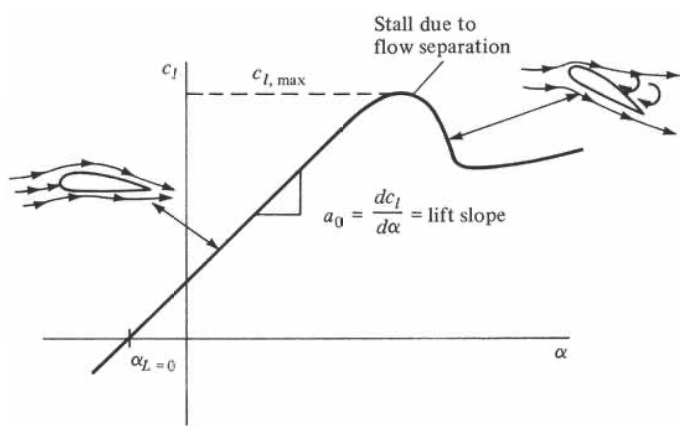


$$C_{l_{\textrm{wf}} } =\left\lbrace n\left(\alpha -\alpha {\;}_{L=0} \right),\textrm{if}\;\alpha \le 14\ldotp 5*\left(\frac{\textrm{pi}}{180}\right)\right\rbrace$$



$$C_{l_{\textrm{wf}} } =\left\lbrace \textrm{a3}\alpha {\;}^3 +\textrm{a2}\alpha {\;}^2 +\textrm{a1}\alpha +\textrm{a0},\textrm{otherwise}\right\rbrace$$


where,   $\begin{array}{l}
\alpha {\;}_{l=0} =-11\ldotp 5*\left(\frac{\textrm{pi}}{180}\right)\\
n=5\ldotp 5\;\textrm{slope}\;\textrm{of}\;\textrm{the}\;\textrm{cl}\;\textrm{curve}\\
\textrm{a3}=-768\ldotp 5\\
\textrm{a2}=609\ldotp 2\\
\textrm{a1}=-155\ldotp 2\\
\textrm{a0}=15\ldotp 212
\end{array}$

- The $C_{L_{\textrm{fs}} }$ is only a function of alpha

- We are including the stall characteristics

- Did not included reverse stall condition

- $C_{L_{\textrm{ef}} }^s$ is in the stability frame

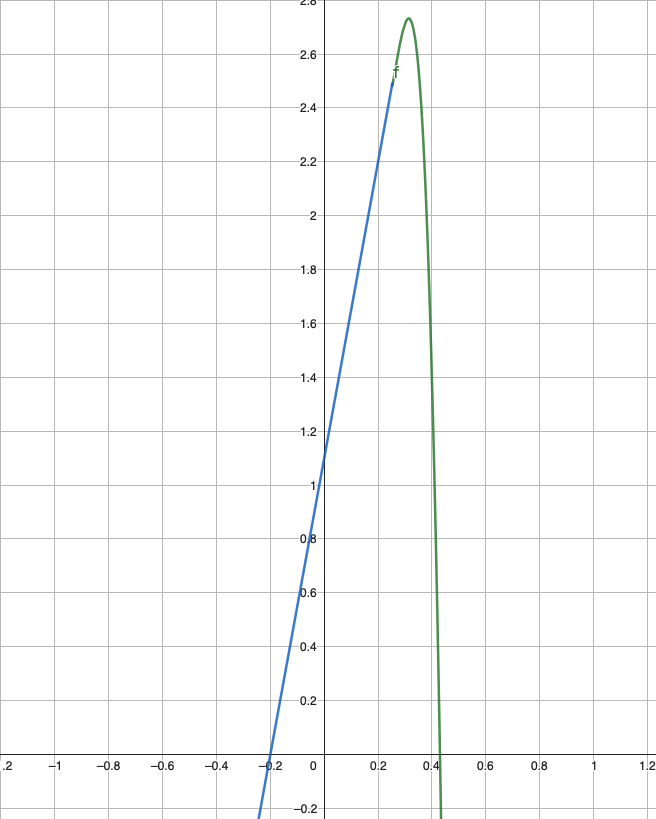

### Lift Generated by the tail

The general equation for the tail angle of attcak is given by 


$$\alpha {\;}_t =\alpha -\epsilon$$


where, $\epsilon$ is downwash parameter

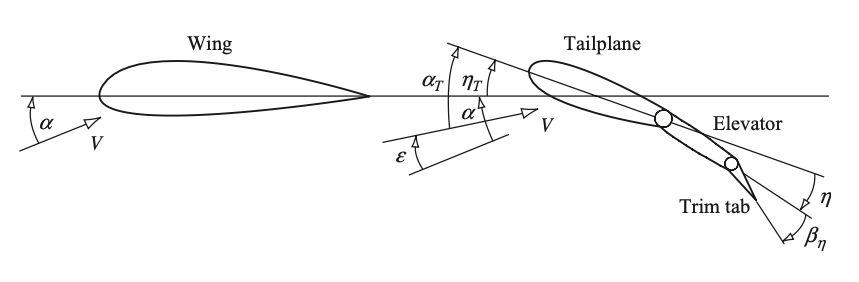

**NOTE**:- Here in the horizontal stabilizer the entire tail goes up and down (all movable tail)


$$\alpha {\;}_t =\alpha -\epsilon +\textrm{u2}+1\ldotp 3*\textrm{X5}\left(\frac{l_t }{V_a }\right)$$


$\omega =\frac{\partial }{\partial \alpha \;}\omega \left(\alpha -\alpha {\;}_{L=0} \right)$  here we are trying to model the downwash

$\frac{\partial }{\partial \alpha \;}\omega$=0.25

$1\ldotp 3*\textrm{X5}\left(\frac{l_t }{V_a }\right)$= Dynamic pitch response of the aircraft

$l_{t=X_{\textrm{ac},t} -X_{\frac{\textrm{cg}}{\textrm{ac}}} } =24\ldotp 8$  Tail moment-arm of the aircarft

The total contribution from the tail is given by 


$$C_{L_t } =3\ldotp 1*\left(\frac{S_t }{S}\right)*\alpha {\;}_t$$



$$\begin{array}{l}
S_t =64m^2 \\
S=260m^2 
\end{array}$$


### Total Lift Coefficient of the aircraft


$$C_L =C_{L_{\textrm{wf}} } +C_{\textrm{Lt}}$$


### Total drag Coefficient is given by

$C_D =0\ldotp 013+0\ldotp 07{\left(5\ldotp 5\alpha +0\ldotp 654\right)}^2$  Till now we can note that there is no beta dependence

### Total Side Force


$$C_y =-1\ldotp 6\beta +0\ldotp 243U_3$$


% Calculate the CL_wb

if alpha<=alpha_switch

      CL_wb=n*(alpha-alpha_L0);
else
      CL_wb=a3*alpha^3+a2*alpha^2+a1*alpha+a0;
end


% Assume a.o.a not highly enough to cause stall
%CL_wb=n*(alpha-alpha_L0);

%Claculate CL_t

epsilon=depsda*(alpha-alpha_L0);
alpha_t=alpha-epsilon+u2+1.3*x5*lt/Va;
CL_t=3.1*(St/S)*alpha_t;

% claculation of the Total lift force
CL=CL_wb+CL_t;

% Total drag force (Neglecting the tail)
CD=0.13+0.07*(5.5*alpha+0.654)^2;

% Calculate the side force
CY=-1.6*beta+0.24*u3;


## DIMENSIONAL AERDOYNAMIC FORCES 

note, here were are rotating the aerodynamic forces from the stability frame to body frame

% calculate the actual dimensional forces. These are in F_s (Stability axis)

FA_s=[-CD*Q*S;CY*Q*S;-CL*Q*S];

## Rotating the forces from the stability frame to body frame

% Rotate these forces to F_b (Body axis)
C_bs=[cos(alpha) 0 -sin(alpha);0 1 0;sin(alpha) 0 cos(alpha)];

FA_b=C_bs*FA_s;


## NON-DIMENSIOANL AERODYNAMIC MOMENT COEFFICIENT ABOUT THE AC IN THE BODY FRAME

Non dimensional Aeromoment coefficient cabout AC in the body frame is given by:-


$${\bar{C_{\textrm{mac}} } }^b =\left\lbrack \begin{array}{c}
C_{\textrm{Lac}} \\
C_{\textrm{mac}} \\
\textrm{Cnac}
\end{array}\right\rbrack =\bar{\eta} +\frac{\partial }{\partial X}{\bar{\omega_{b\backslash e} } }^b +\frac{\partial }{\partial U}C_m \left\lbrack \begin{array}{c}
\textrm{u1}\\
\textrm{u2}\\
\textrm{u3}
\end{array}\right\rbrack$$


where,


$$\bar{\eta} =\left\lbrack \begin{array}{c}
-1,4\beta \;\\
-0\ldotp 59-3\ldotp 1\left(S_t \frac{l_t }{S\bar{C} }\right)\left(\alpha -\epsilon \right)\\
\left(1-\alpha *\frac{180}{15\pi \;}\right)\beta \;
\end{array}\right\rbrack$$



$$\frac{\partial }{\partial X}{\bar{\omega_{b\backslash e} } }^b \left\lbrack \begin{array}{ccc}
-11 & 0 & 5\\
0 & -4\ldotp 03*\left(S_t \frac{l_t^2 }{S\bar{C} }\right) & 0\\
1\ldotp 7 & 0 & -11\ldotp 5
\end{array}\right\rbrack *\left(\frac{\bar{C} }{V_A }\right)$$



$$\frac{\partial }{\partial U}C_m =\left\lbrack \begin{array}{ccc}
-0\ldotp 6 & 0 & 0\ldotp 22\\
0 & -3\ldotp 1*\left(S_t *\frac{l_t }{S\bar{C} }\right) & 0\\
0 & 0 & -0\ldotp 63
\end{array}\right\rbrack$$


%Calculate the moments in Fb.  Define eta,dCMdx and dCMdu

eta11=-1.4*beta;
eta21=-0.59-(3.1*(St*lt)/(S*cbar))*(alpha-epsilon);
eta31=(1-alpha*(180/(15*pi)))*beta;


eta=[eta11;eta21;eta31];

dCMdx=(cbar/Va)*[-11 0 5;0 (-4.03*(St*lt^2)/(S*cbar^2)) 0;1.7 0 -11.5]; % needed correcction

dCMdu=[-0.6 0 0.22;0 (-3.1*(St*lt)/(S*cbar)) 0;0 0 -0.63];

% Now calculate CM=[cl;cm;cn] about aerodynamic center in Fb
CMac_b=eta+dCMdx*wbe_b+dCMdu*[u1;u2;u3];


## AERODYNAMIC MOMENT ABOUT AC IN THE BODY FRAME


$${\bar{M_{A_{\textrm{ac}} } } }^b =\bar{\bar{C_{\textrm{mac}}^b } \ldotp \textrm{qS}\bar{C} }$$



%Normalize to an aerodynamic moments

MAac_b=CMac_b*Q*S*cbar;


## AERODYNAMIC MOMENT ABOUT CG IN BODY FRAME

For moment transfer is given by

$\bar{M_{A_{\textrm{cg}} }^b } ={\bar{M_{A_{\textrm{ac}} } } }^b +\bar{F_A^b X\left(\bar{r_{\textrm{cg}}^b } -\bar{r_{\textrm{ac}}^b } \right)}$  equation for the moment transfer


$$\bar{r_{\textrm{cg}}^b =} \left\lbrack \begin{array}{c}
X_{\textrm{cg}} \\
Y_{\textrm{cg}} \\
Z_{\textrm{cg}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\ldotp 23\bar{C} \\
0\bar{C} \\
0\ldotp 10\bar{C} 
\end{array}\right\rbrack$$



$$\bar{r_{\textrm{ac}}^b } =\left\lbrack \begin{array}{c}
X_{\textrm{Ac}} \\
Y_{\textrm{ac}} \\
Z_{\textrm{ac}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\ldotp 12\bar{C} \\
0\\
0
\end{array}\right\rbrack$$


%Transfer moment to CG

rcg_b=[Xcg;Ycg;Zcg];
rac_b=[Xac;Yac;Zac];

MAcg_b=MAac_b+cross(FA_b,rcg_b-rac_b);


## PROPULSION EFFECTS

Forces and Moments due to engine


$$F_1 =\textrm{U4}*\textrm{mg}$$



$$F_2 =\textrm{U5}*\textrm{mg}$$


thrust to weight ratio of the aircraft is given by


$$\frac{\left(F_{1_{\max } } +F_{2_{\max } } \right)}{\textrm{mg}}=0\ldotp 35$$



$$\bar{F_{E_i }^b } =\left\lbrack \begin{array}{c}
F_i \\
0\\
0
\end{array}\right\rbrack$$


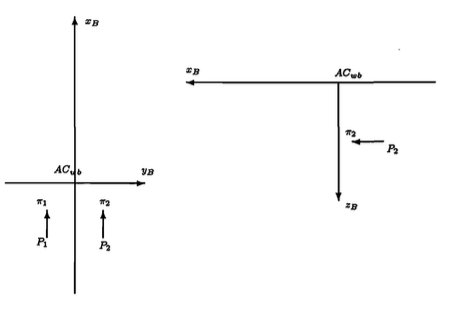

Total Propulsive force in the body frame is given by


$$\bar{F_E^b } =\bar{F_{\textrm{E1}}^b } +\bar{F_{\textrm{E2}}^b }$$



$$\bar{M_{E_{\textrm{cgi}} }^b } =\bar{\mu_i^b } X\bar{F_{\textrm{Ei}}^b }$$


where, $\bar{\mu_i^b } =\left\lbrack \begin{array}{c}
X_{\textrm{cg}} -X_{{\textrm{apt}}_i } \\
Y_{{\textrm{apt}}_i } -Y_{\textrm{cg}} \\
Z_{\textrm{cg}} -Z_{{\textrm{apt}}_i } 
\end{array}\right\rbrack$ is the distance between the CG of the aircraft and the application point of thrust.

Data for the above matrix

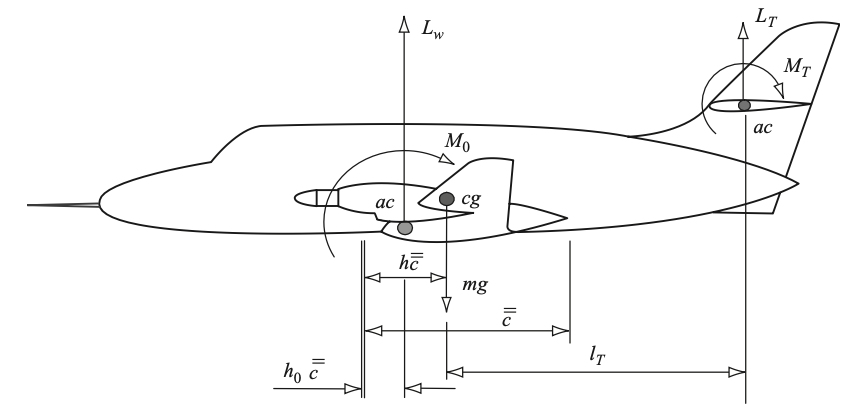


$$\begin{array}{l}
X_{{\textrm{apt}}_1 } =0m\\
Y_{{\textrm{apt}}_i =} -7\ldotp 94m\\
Z_{{\textrm{apt}}_1 } =-1\ldotp 9m\\
X_{{\textrm{apt}}_2 } =0m\\
Y_{{\textrm{apt}}_2 } =7\ldotp 94m\\
Z_{{\textrm{apt}}_2 } =-1\ldotp 9m
\end{array}$$


% First, calculate the thrust of each engine

F1=u4*m*g;
F2=u5*m*g;

%Assuming that the engine thrust is aligned with the Fb, we have

FE1_b=[F1;0;0];
FE2_b=[F2;0;0];

FE_b=FE1_b+FE2_b;

%Now the engine moment due to offset of engine thrust from cog

mew1=[Xcg-Xapt1;Yapt1-Ycg;Zcg-Zapt1];
mew2=[Xcg-Xapt2;Yapt2-Ycg;Zcg-Zapt2];

MEcg1_b=cross(mew1,FE1_b);
MEcg2_b=cross(mew2,FE2_b);

MEcg_b=MEcg1_b+MEcg2_b;



## GRAVITY EFFECTS

Here we are considering the gravity effects to the aircraft


$$\bar{F_g } =m\bar{g}$$


Let us consider earth frame Fe


$$\bar{F_g^e } =\left\lbrack \begin{array}{c}
0\\
0\\
g
\end{array}\right\rbrack$$


We need to rotate to the body frame


$$\bar{F_g^b } =C_{\frac{b}{e}} \left(\phi \;\theta \;\psi \;\right){\bar{F} }_g^e$$



$$\bar{F_g^b } =\left\lbrack \begin{array}{c}
-\textrm{gsin}\left(\textrm{X8}\right)\\
\textrm{gcosX8}*\textrm{sinX7}\\
\textrm{gcosX8}*\textrm{cosX7}
\end{array}\right\rbrack$$


$\bar{M_{{\textrm{cg}}_g }^b } =0$ as the gravity acts at the CG of the aircraft


% Calculate the gravitational forces in the body frame. This causes no moments abot the CG


g_b=[-g*sin(x8);g*cos(x8)*sin(x7);g*cos(x8)*cos(x7)];

Fg_b=m*g_b;


## EXPLICIT FIRST ORDER FORM

## Cosidering the FLAT EARTH EQUATIONS

$\left\lbrack \begin{array}{c}
\dot{X_1 } \\
\dot{X_2 } \\
\dot{X_3 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{u} \\
\dot{v} \\
\dot{w} 
\end{array}\right\rbrack =\frac{1}{m}*\bar{F^b } -\bar{\omega_{\frac{b}{e}}^b } \;X\;{\bar{V} }^b$   Assuming that the mass is constant

where, ${\bar{F} }^b =\bar{F_b^b } +\bar{F_E^b } +\bar{F_A^b }$


$$\left\lbrack \begin{array}{c}
\dot{X_4 } \\
\dot{X_5 } \\
\dot{X_6 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{p} \\
\dot{q} \\
\dot{r} 
\end{array}\right\rbrack =I_b^{-1} \left(\bar{M_{\textrm{cg}}^b } -\bar{\omega_{\frac{b}{e}}^b } \;X\;I_b \bar{\omega_{\frac{b}{e}}^b } \right)$$


where, $\bar{M_{\textrm{cg}}^b } =\bar{M_{E_{\textrm{cg}} }^b } +\bar{M_{A_{\textrm{cg}} }^b }$

$\left\lbrack \begin{array}{c}
\dot{X_7 } \\
\dot{X_8 } \\
\dot{X_9 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{\phi \;} \\
\dot{\theta \;} \\
\dot{\psi \;} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & \sin \phi \;\tan \theta \; & \cos \phi \;\tan \theta \;\\
0 & \cos \phi \; & -\sin \phi \;\\
0 & \sin \phi \;\cos \theta \; & \cos \phi \;\cos \theta \;
\end{array}\right\rbrack {\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack }^b$      Euler Kinematical equation

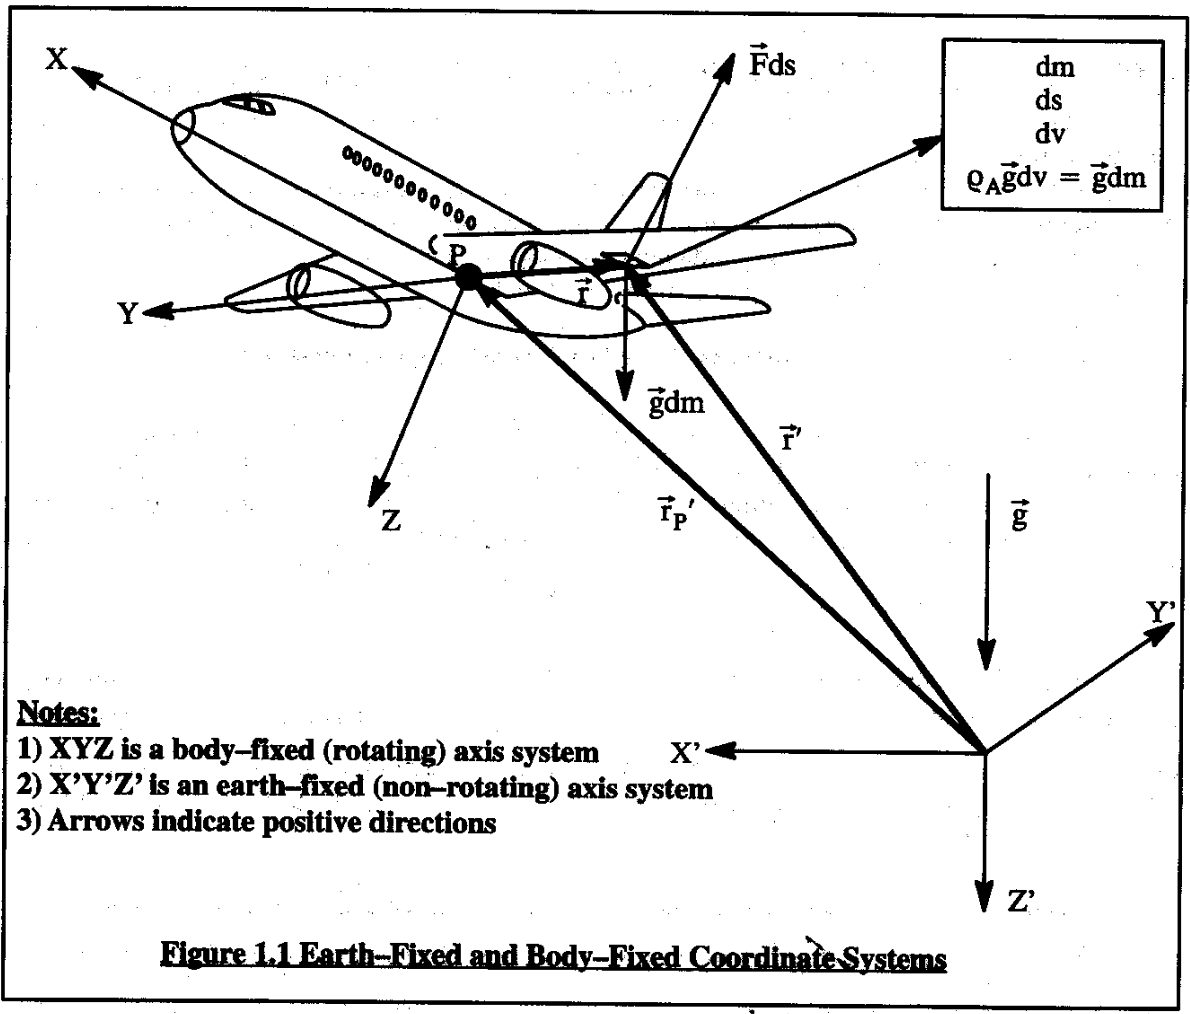


%Inertia matrix

Ib=m*[40.07 0 -2.0923;0 64 0;-2.0923 0 99.92];

% Inverse of the inertia matrix

invIb=(1/m)*[0.0249836 0 0.000523151;0 0.015625 0;0.000523215 0 0.010019];


% From F_b ( all the forces in Fb ) and calculate the udot, vdot,wdot

F_b=Fg_b+FE_b+FA_b;

x1to3dot=(1/m)*F_b-cross(wbe_b,V_b);

%From Mcg_b (all the moments about the cog in Fb) and calculate pdot,qdpt,rdoot

Mcg_b=MAcg_b+MEcg_b;

x4to6dot=invIb*(Mcg_b-cross(wbe_b,Ib*wbe_b));

% Calculation of the phidot,thetadot,psidot

H_pi=[1 sin(x7)*tan(x8) cos(x7)*tan(x8);0 cos(x7) -sin(x7);0 sin(x7)/cos(x8) cos(x7)/cos(x8)];

x7to9dot=H_pi*wbe_b;


## NAVIGATION EQUATION

To calculate the position of the aircraft in North, East and Down Direction

$C_{\frac{b}{v}} \left(\phi \;\theta \;\psi \;\right)=C_{\frac{b}{2}} \ldotp C_{\frac{2}{1}} \ldotp C_{\frac{1}{v}}$     Direction cosine matrix

$\bar{V^v } =C_{\frac{b}{v}}^T *\bar{V^b }$     Navigational Eqaution


$$\bar{V^v } =\left\lbrack \begin{array}{c}
V_N \\
V_E \\
V_D 
\end{array}\right\rbrack$$



$$\dot{h} =-V_D$$


% Rotational Matrix from the 1 frame to 2 frame

C1v=[cos(x9) sin(x9) 0;
    -sin(x9) cos(x9) 0;
    0 0 1];

% Rotational Matrix from the 1 frame to 2 frame

C21=[cos(x8) 0 -sin(x8);
    0 1 0;
    sin(x8) 0 cos(x8)];

% Rotational Matrix from the 1 frame to 2 frame

Cb2=[1 0 0;
    0 sin(x7) cos(x7);
    0 -sin(x7) cos(x7)];

% Implimenting the Navigational Equation
Cbv=Cb2*C21*C1v;

Cvb=Cbv';

x10to12dot=Cvb*V_b;



## EXPLICIT FIRST ORDER FORM


$$\dot{X} =\left\lbrack \begin{array}{c}
X_1 \\
X_2 \\
X_3 \\
X_4 \\
X_5 \\
X_6 \\
X_7 \\
X_8 \\
X_9 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{u} \\
\dot{v} \\
\dot{w} \\
\dot{p} \\
\dot{q} \\
\dot{r} \\
\dot{\phi \;} \\
\dot{\theta \;} \\
\dot{\psi \;} 
\end{array}\right\rbrack$$



$$\dot{X=\left\lbrack \begin{array}{c}
X_{10} \\
X_{11} \\
X_{12} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
V_N \\
V_E \\
V_D 
\end{array}\right\rbrack }$$


XDOT=[x1to3dot;
    x4to6dot;
    x7to9dot;
    x10to12dot;
    ];

